# **整体优化**

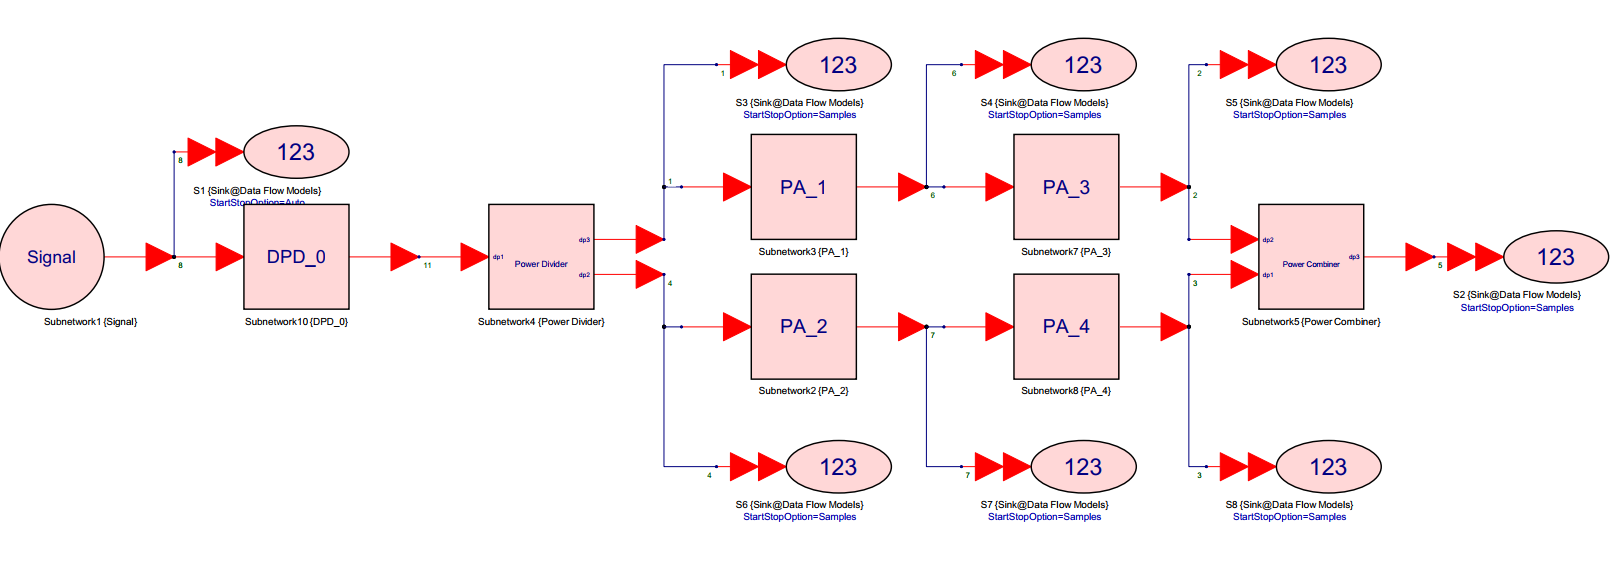

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Original System----------------------------

此模型是完全固定的！

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[U1,D1]=Power_Divider(Sys_input);
U2=PA_1(U1);
U3=PA_3(U2);
D2=PA_2(D1);
D3=PA_4(D2);
Original_output_sim=Power_Combiner(U3,D3);
% 性能评估
err=abs(Original_output_sim-Original_output) %模型本身的误差

err = 1.0e-13 *

    0.0037
    0.0030
    0.0057
    0.0049
    0.0051
    0.0050
    0.0098
    0.0063
    0.0109
    0.0111


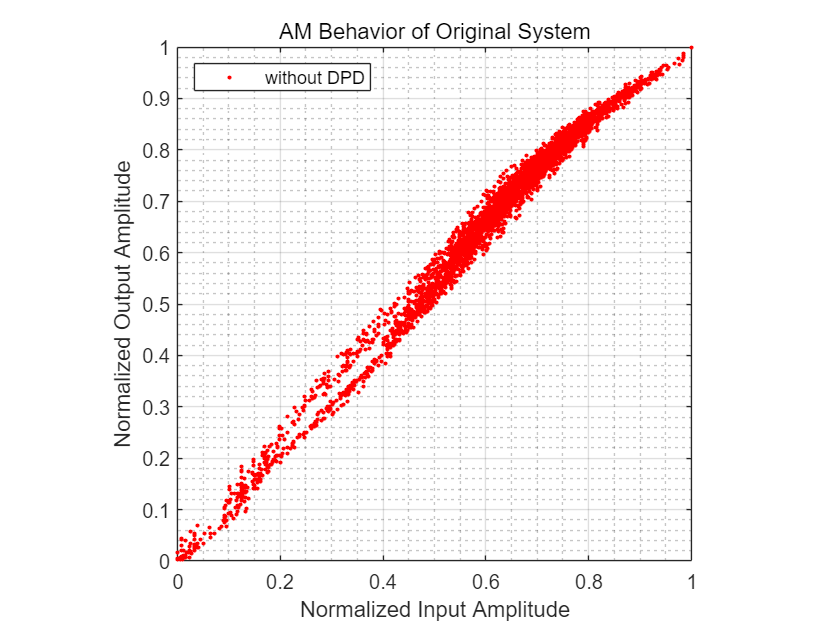

Plot_AM(Sys_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Sys_input,Original_output_sim);
nmse_act = NMSE_dB(Sys_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -16.688242 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -16.688242 dB


## -----------------------------Model A2 System----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
% 根据需要选取原始数据
Sys_x_i=Data_matrix(:,1);Sys_x_q=Data_matrix(:,2);
Sys_y_i=Data_matrix(:,15);Sys_y_q=Data_matrix(:,16);
Sys_input = Sys_x_i + 1i * Sys_x_q;
Sys_output = Sys_y_i + 1i * Sys_y_q;

## 整体训练(训练一次即可)

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　１．３１　｜　　　　　　１．２４　｜　　０．８５７２　｜　０．７６３０　｜　　０．００３０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０２　｜　　　　　　　０．１０　｜　　　　　　０．１２　｜　　０．００５４　｜　０．００６９　｜　　０．００３０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０３　｜　　　　　　　０．０８　｜　　　　　　０．０８　｜　　０．００３１　｜　０．００３０　｜　　０．００３０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０５　｜　　　　　　　０．０７　｜　　　　　　０．０８　｜　　０．００２７　｜　０．００３５　｜　　０．００３０　｜
｜　３２０　｜　　３２０　｜　　　　　００：００：０８　｜　　　　　　　０．０６　｜　　　　　　０．０６　｜　　０．００１９　｜　０．００１８　｜　　０．００３０　｜
｜　４００　｜　　４００　｜　　　　　００：００：１２　｜　　　　　　　０．０４　｜　　　　　　０．０８　｜　　０．００１０　｜　０．００３２　｜　　０．００３０　｜
｜　４８０　｜　　４８０　｜　　　　　００：００：１５　｜　　　　　　　０．０６　｜　　　　　　０．０６　｜　　０．００１７　｜　０．００１７　｜　　０．００３０　｜
｜　５６０　｜　　５６０　｜　　　　　００：００：１９　｜　　　　　　　０．０６　｜　　　　　　０．０５　｜　　０．００１７　｜　０．００１２　｜　　０

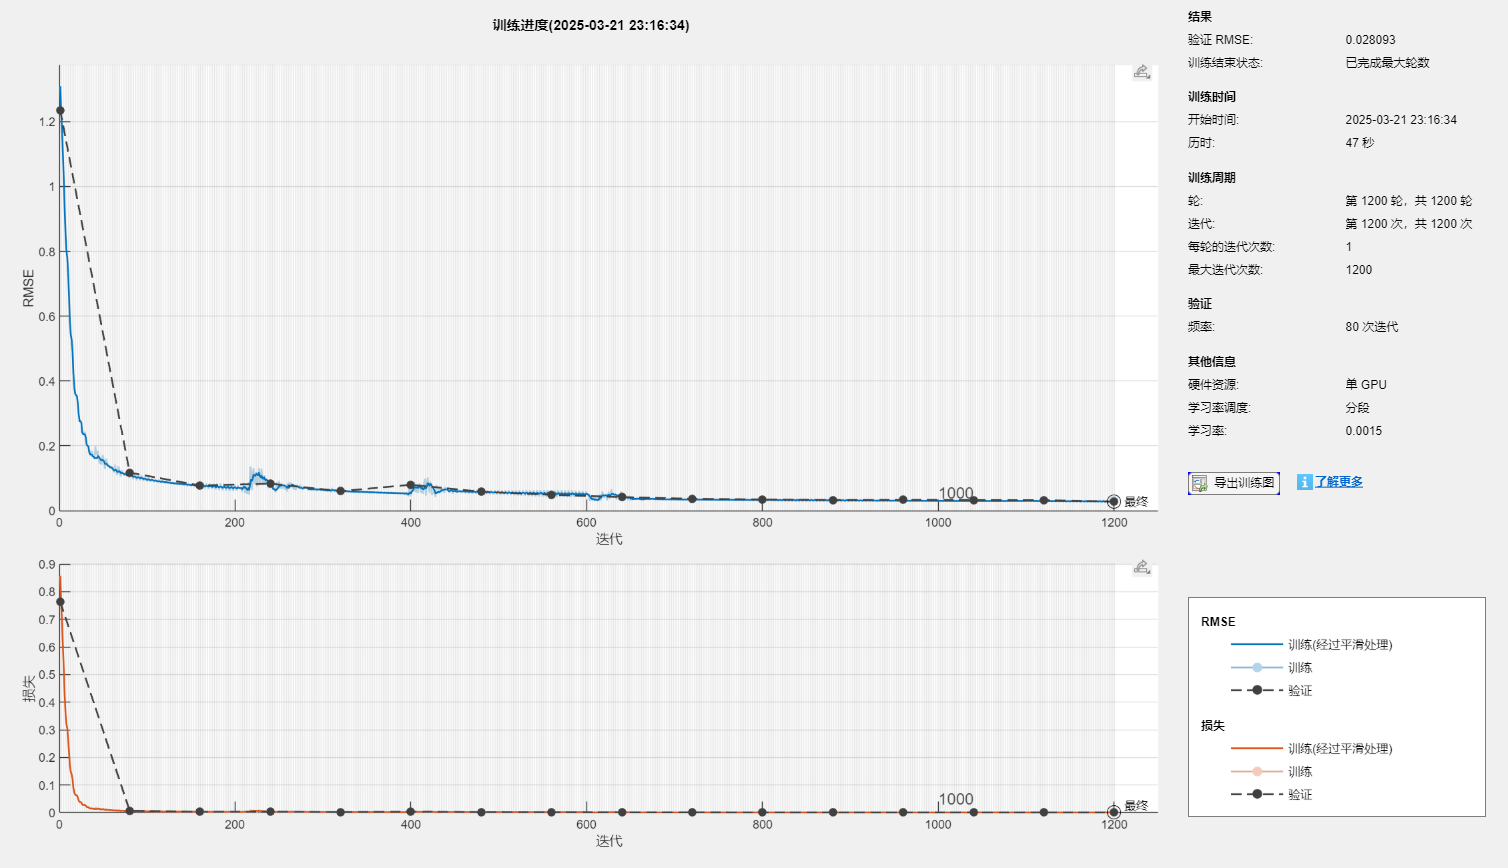

Simple_FCN =   SeriesNetwork - 属性:

         Layers: [17×1 nnet.cnn.layer.Layer]
     InputNames: {'sequence'}
    OutputNames: {'regressionoutput'}


% %%%%%%%%%%%%%%%%%%%%%%%%%% 1：FNN %%%%%%%%%%%%%%%%%%%%%%%%%%
% FNN = FNN_train(Sys_x_i,Sys_x_q,Sys_y_i,Sys_y_q,7);
% save('Algorithm_B\Alg_Whole.mat', 'FNN','-append');

% %%%%%%%%%%%%%%%%%%%%%%%%%% 4：DNN %%%%%%%%%%%%%%%%%%%%%%%%%%
% DNN = DNN_train(Sys_x_i,Sys_x_q,Sys_y_i,Sys_y_q,7);
% save('Algorithm_B\Alg_Whole.mat', 'DNN','-append');

%%%%%%%%%%%%%%%%%%%%%%%%%% 10：Simple FCN %%%%%%%%%%%%%%%%%%%%%%%%%%
Simple_FCN=simpleFCN_train(Sys_x_i,Sys_x_q,Sys_y_i,Sys_y_q,7);

save('Algorithm_B\Alg_Whole.mat', 'Simple_FCN','-append');

## Model Test

% 参数需要保持一致
M = 7;
% 系统模拟
Sys_input_DPD=DPD(Sys_input,M,10,'Algorithm_B\Alg_Whole.mat');
[S_U1,S_D1]=Power_Divider(Sys_input_DPD);
S_U2    = PA_1(S_U1);
S_U3    = PA_3(S_U2);
S_D2    = PA_2(S_D1);
S_D3    = PA_4(S_D2);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
nmse_DPD=Get_nmse_DPD(Sys_output_sim,Sys_output);
fprintf('单级DPD的相对NMSE为 %f dB\n', nmse_DPD);

单级DPD的相对NMSE为 -17.265864 dB


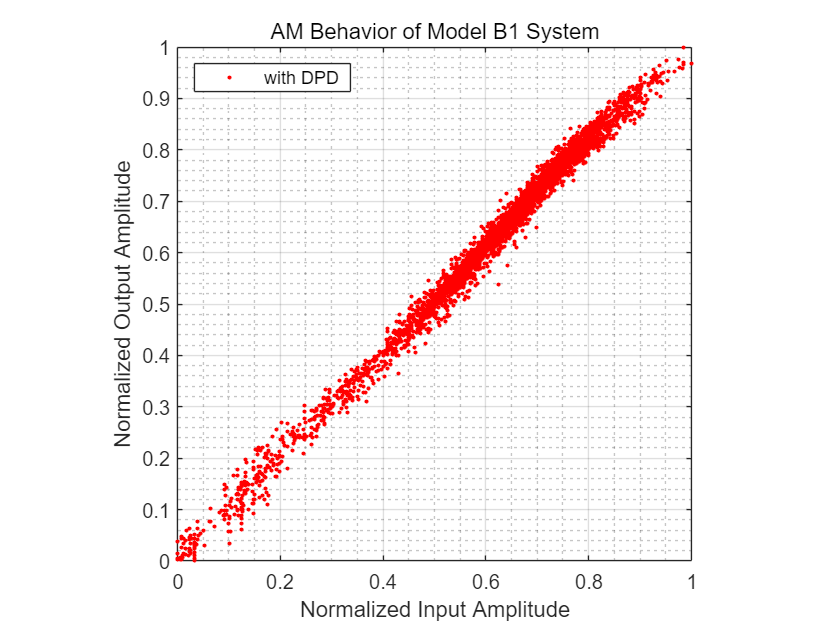

Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model B1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model A2，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model A2，系统的NMSE仿真结果为 -25.789648 dB
